data = readtable('/Users/yossi/PDaMSoC-data/X1+Y1/distances_no_x1_15.csv');
X1 = readtable("X1+Y1/distances_X1.csv");
X1_df = readtable("X1/X1_df.csv");
Y1 = readtable("X1+Y1/distances_Y1.csv");
Y1_df = readtable("Y1/Y1_df.csv");
data.Properties.RowNames = data.Var1;
X1.Properties.RowNames = X1.Var1;
Y1.Properties.RowNames = Y1.Var1;
% X1_df.Properties.RowNames = X1_df.Var1;
% Y1_df.Properties.RowNames = Y1_df.Var1;
X1_cols = [
    0.0 1 1;      %cyan
     0.3600,    0.6100,         0; %green
     0.8000, 0,      1.0000;  %3 purple 
1,      0.000, 0.0000; %red
    0,0,0; %5 black
    ];

data=removevars(data, "Var1");
X1 = removevars(X1, "Var1");
Y1 = removevars(Y1, "Var1");
X1_df = removevars(X1_df, "Var1");
Y1_df = removevars(Y1_df, "Var1");
numericData = table2array(data);
numericX1 = table2array(X1);
numericY1 = table2array(Y1);
% Display the first few rows of the data
N = max(size(numericData));
NX = max(size(numericX1));
NY = max(size(numericY1));
nClusters = 9;

X1_clusters = readtable("mlab_clusters_X1.csv");
X1_clusters.Properties.RowNames=X1_clusters.Row;

X1_clusters = removevars(X1_clusters, "Row");


tree1=linkage(numericData,'average');
figure
cutoff = median([tree1(end-nClusters+1,3) tree1(end-nClusters+2, 3)]);
[h1,t1,p1]=dendrogram(tree1,0,'ColorThreshold',cutoff);
set(h1,'LineWidth',1.5);
xticks([])
yticks([])
% xlabel({"X1+Y1 Average Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
%
% Collect colors
%
% We use four colors, that are in order:
% Cluster 1: red
% Cluster 2: purple
% Cluster 3: cyan
% Cluster 4: green
%
for i = 1:length(h1)
        h1(i).Color = [0, 0, 0]; % RGB for black
end


for iLeaf = 1:N
    cell = data.Properties.RowNames{iLeaf};
    if contains(cell, "X1")
        clusId = X1_clusters{cell, "Cluster"};
        if clusId ==2
            cell
        end
        numericData_color(iLeaf,:) = X1_cols(clusId, :); 
    elseif contains(cell, "Y1")
        numericData_color(iLeaf,:) = [0,0,0]; % Default color for others
    end
end

cell = 'X1_66'

cell = 'X1_61'

cell = 'X1_11'

cell = 'X1_7'

cell = 'X1_31'

cell = 'X1_9'

cell = 'X1_52'

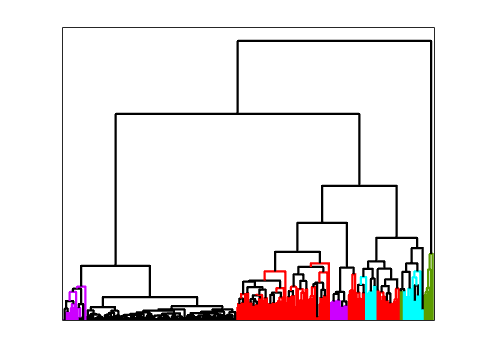


for iLeaf = 1:N
    [iRow, ~] = find(tree1==iLeaf);
    h1(iRow).Color = numericData_color(iLeaf,:);
end

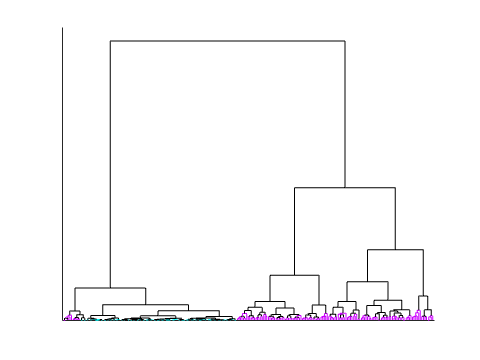

% Perform hierarchical clustering
Z = linkage(numericData, 'ward'); % Choose your linkage method
figure;
cutoff = median([Z(end-2+1,3) Z(end-2+2, 3)]);

[H, T] =dendrogram(Z,0,'ColorThreshold',cutoff);

% Get the leaf labels
leafLabels = data.Properties.RowNames; % Assuming T contains the labels

for i = 1:length(H)
        H(i).Color = [0, 0, 0]; % RGB for black
end


for iLeaf = 1:N
    [iRow, ~] = find(Z==iLeaf);
    cell = leafLabels{iLeaf};
    if contains(cell, "X1")
        H(iRow).Color = [0.8,0,1];
    elseif contains(cell, "Y1")
        H(iRow).Color = [0,1,1]; % Default color for others
    end
    
end
xticks([])
yticks([])


%
%============================================
% Generate HC with complete linkage
%============================================
%
tree2=linkage(numericData,'complete');
%
% Generate clustering and drendrogram
%
figure
h2=dendrogram(tree2,0);
set(h2,'Color','k');
set(h2,'LineWidth',1.5);
% 
% Recolor based on colors of average clustering
%
for iLeaf = 1:N
	[iRow, ~] = find(tree2==iLeaf);
	set(h2(iRow), 'Color', numericData_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"X1+Y1 Complete Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;


% savefig("X1+Y1_complete.fig")
%============================================
% Generate HC with single linkage
%============================================
%
tree3=linkage(numericData,'single');
%
% Generate clustering and drendrogram
%
figure
h3=dendrogram(tree3,0);
set(h3,'Color','k');
set(h3,'LineWidth',1.5);
% 
% Recolor based on colors of average clustering
%
for iLeaf = 1:N
	[iRow, ~] = find(tree3==iLeaf);
	set(h3(iRow), 'Color', numericData_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"X1+Y1 Single Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;

% savefig("X1+Y1_single.fig")

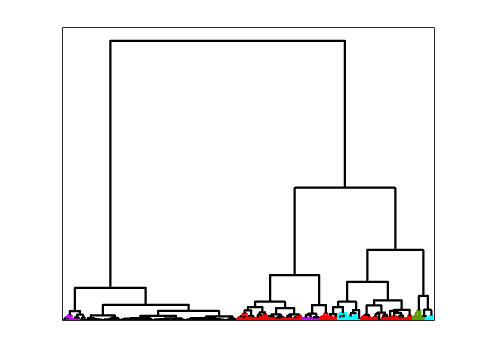


%============================================
% Generate HC with ward linkage
%============================================
%
tree4=linkage(numericData,'ward');

%
% Generate clustering and drendrogram
%
figure
h4=dendrogram(tree4,0);
set(h4,'Color','k')
set(h4,'LineWidth',1.5)
% 
% Recolor based on colors of average clustering
%
for iLeaf = 1:N
	[iRow, ~] = find(tree4==iLeaf);
	set(h4(iRow), 'Color', numericData_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"X1+Y1 Ward Linkage"});
% yticklabels({});
box on

gca.LineWidth=1;

savefig("X1+Y1_ward.fig")


%============================================
% Perform MDS
%============================================
%
[Y e]=cmdscale(numericData,2);

figure
hold on
for iLeaf=1:N
    plot(Y(iLeaf,1),Y(iLeaf,2), 'o','Color',numericData_color(iLeaf,:), 'LineWidth',1.5);
end
xticks([])
% yticks([])
xlabel({"X1+Y1 MDS"});
% yticklabels({});
box on
gca.LineWidth=1;
% savefig("numericData_mds.fig")

figure
hold on
[Y e]=cmdscale(numericData,2);
X1_cols = [
    1.0000, 0,      0;      % Red
    0.0 1.0 1.0;      % Yellow-Green
    0.3600,    0.6100,         0; % Green
    0,      0.000, 0.0000; % Black
    0.8000, 0,      1.0000; % Purple
    0,      0,      0       % Black
    ];
% X1_cols = hsv(5);
% [0.36 0.61 0.00][0.5 1.0 0]
for i = 1:N
    cell = data.Properties.RowNames{i};
    if contains(cell, "Y1")
        plot (Y(i,1),Y(i,2), "o", "Color", [1,0,1], 'LineWidth',1.5);
    elseif contains(cell, "X1")
           X1_rowId = strcmp(X1_df.Properties.RowNames, cell);
           clusId = X1_df.("average5")(X1_rowId)+1;
           plot (Y(i,1),Y(i,2), "o", "Color", X1_cols(clusId,:), 'LineWidth',1.5);
    end
end

% X1
nClusters = 5;

tree1=linkage(numericX1,'average');
figure
cutoff = median([tree1(end-nClusters+1,3) tree1(end-nClusters+2, 3)]);
h1=dendrogram(tree1,0,'ColorThreshold',cutoff);
set(h1,'LineWidth',1.5);
xticks([])
yticks([])
% xlabel({"X1 Average Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
%
% Collect colors
%
% We use four colors, that are in order:
% Cluster 1: red
% Cluster 2: purple
% Cluster 3: cyan
% Cluster 4: green
%
cyan=[0 1.0 1.0];
lineColours1 = cell2mat(get(h1,'Color'));
colorList1 = unique(lineColours1, 'rows');

colorList = [
    1.0000, 0,      0;      % Red
    0.0 1.0 1.0;      % Yellow-Green
    0.3600,    0.6100,         0; % Green
    0,      0.000, 0.0000; % Black
    0.8000, 0,      1.0000; % Purple
    0,      0,      0       % Black
    ];
%colorList(9,:) = [1 0 1];
for iLeaf = 1:NX
    [iRow, ~] = find(tree1==iLeaf);
    color = lineColours1(iRow,:);
    % assign color to each observation
    numericX1_color(iLeaf,:) = color; 
    numericX1_cluster(iLeaf,1) = iLeaf;
    numericX1_cluster(iLeaf,2) = find(ismember(colorList1, color, 'rows')); 
end





% Perform hierarchical clustering
tree1 = linkage(numericX1, 'average'); % Choose your linkage method
figure;
cutoff = median([tree1(end-nClusters+1,3) tree1(end-nClusters+2, 3)]);

[H, T] =dendrogram(tree1,0,'ColorThreshold',cutoff);;

% Get the leaf labels
leafLabels = X1_df.Properties.RowNames; % Assuming T contains the labels

% Initialize color array
colors = zeros(length(leafLabels), 3); % RGB colors


% Loop through each label and assign colors
for i = 1:length(leafLabels)
    cell = leafLabels{i};
    if contains(cell, 'Y1')
        colors(i, :) = [0, 0, 0]; % Red for X1
    elseif contains(leafLabels{i}, 'X1')
        X1_rowId = strcmp(X1_df.Properties.RowNames, cell);
        clusId = X1_df.("average5")(X1_rowId)+1;
        colors(i,:) = X1_cols(clusId, :); 
    else
        colors(i, :) = [0, 0, 0]; % Black for others
    end
end

% Update the dendrogram with new colors
for i = 1:length(H)
    set(H(i), 'Color', colors(i, :));
end
xticks([])
yticks([])
title('Dendrogram with Colored Leaves');




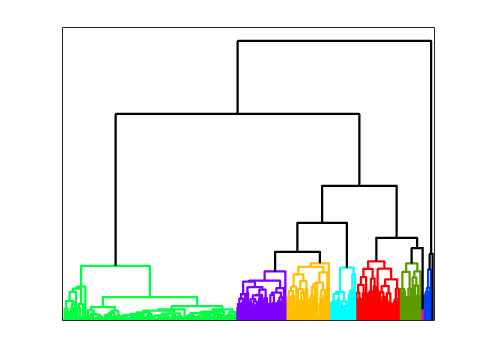

% X1+Y1
% Generate HC with average linkage
%============================================
%
%============================================

tree1=linkage(numericData,'average');

%
% Generate figure with 4 clusters
%
figure
cutoff = median([tree1(end-nClusters+1,3) tree1(end-nClusters+2, 3)]);
h1=dendrogram(tree1,0,'ColorThreshold',cutoff);
set(h1,'LineWidth',1.5);
xticks([])
yticks([])
% xlabel({"X1+Y1 Average Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
%
% Collect colors
%
% We use four colors, that are in order:
% Cluster 1: red
% Cluster 2: purple
% Cluster 3: cyan
% Cluster 4: green
%
cyan=[0 1.0 1.0];
lineColours1 = cell2mat(get(h1,'Color'));
colorList1 = unique(lineColours1, 'rows');
check = ismember(cyan,colorList1,'rows');
check = not(check);
colorList = hsv(nClusters);
%colorList(9,:) = [1 0 1];
for iLeaf = 1:N
	[iRow, ~] = find(tree1==iLeaf);
	color = lineColours1(iRow,:);
	% assign color to each observation
	numericData_color(iLeaf,:) = color; 
	numericData_cluster(iLeaf,1) = iLeaf;
	numericData_cluster(iLeaf,2) = find(ismember(colorList1, color, 'rows')); 
end
for i = 1:size(h1,1)
    if h1(i).Color == [0.5 1.0 0];
        h1(i).Color = [0.36 0.61 0.00];
    end
end

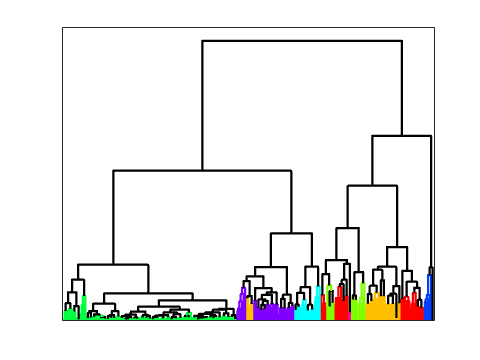

% savefig("X1+Y1_average.fig")
%
%============================================
% Generate HC with complete linkage
%============================================
%
tree2=linkage(numericData,'complete');
%
% Generate clustering and drendrogram
%
figure
h2=dendrogram(tree2,0);
set(h2,'Color','k');
set(h2,'LineWidth',1.5);
% 
% Recolor based on colors of average clustering
%
for iLeaf = 1:N
	[iRow, ~] = find(tree2==iLeaf);
	set(h2(iRow), 'Color', numericData_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"X1+Y1 Complete Linkage"});
% yticklabels({});
box on

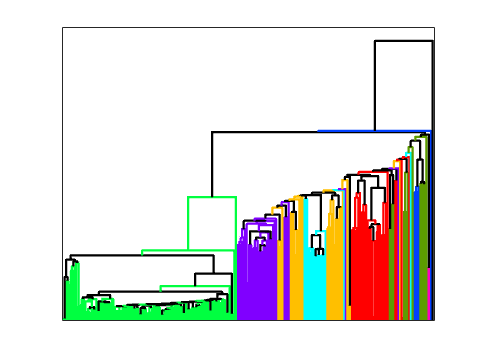

gca.LineWidth=1;

% savefig("X1+Y1_complete.fig")
%============================================
% Generate HC with single linkage
%============================================
%
tree3=linkage(numericData,'single');
%
% Generate clustering and drendrogram
%
figure
h3=dendrogram(tree3,0);
set(h3,'Color','k');
set(h3,'LineWidth',1.5);
% 
% Recolor based on colors of average clustering
%
for iLeaf = 1:N
	[iRow, ~] = find(tree3==iLeaf);
	set(h3(iRow), 'Color', numericData_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"X1+Y1 Single Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
for i = 1:size(h3,1)
    if h3(i).Color == [0.5 1.0 0];
        h3(i).Color = [0.36 0.61 0.00];
    end
end

% savefig("X1+Y1_single.fig")

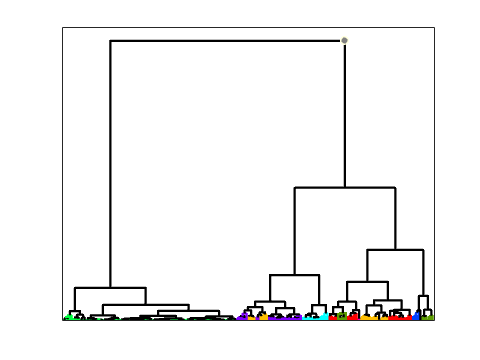


%====================================
% ========
% Generate HC with ward linkage
%============================================
%
tree4=linkage(numericData,'ward');
%
% Generate clustering and drendrogram
%
figure
h4=dendrogram(tree4,0);
set(h4,'Color','k')
set(h4,'LineWidth',1.5)
% 
% Recolor based on colors of average clustering
%
for iLeaf = 1:N
	[iRow, ~] = find(tree4==iLeaf);
	set(h4(iRow), 'Color', numericData_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"X1+Y1 Ward Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
for i = 1:size(h4,1)
    if h4(i).Color == [0.5 1.0 0];
        h4(i).Color = [0.36 0.61 0.00];
    end
end

% savefig("X1+Y1_ward.fig")


%============================================
% Perform MDS
%============================================
%
[Y e]=cmdscale(numericData,2);

figure
hold on
for iLeaf=1:N
    plot(Y(iLeaf,1),Y(iLeaf,2), 'o','Color',numericData_color(iLeaf,:), 'LineWidth',1.5);
end
xticks([])
% yticks([])
xlabel({"X1+Y1 MDS"});
% yticklabels({});
box on
gca.LineWidth=1;
% savefig("numericData_mds.fig")


